# Test convolution with FFT and conv2

## 快速傅里叶变换(FFT)中为什么要“补零”？

Copyright @ [知乎](https://zhuanlan.zhihu.com/p/85863024)

参考

- Zero Padding http://www.bitweenie.com/listings/fft-zero-padding/

- Zero Padding Theorem https://ccrma.stanford.edu/~jos/dft/Zero_Padding_Theorem_Spectral.html

### 快速傅里叶变换 FFT

比如有一个信号，这个信号中仅包含两个正（余）弦波，一个是 1MHz ，一个是 1.05 MHz ，即 $x=\cos(2\pi \times 1000000t) + \cos(2\pi\times  1050000t)$。设定采样频率为$f_s = 100$ MHz ，如果采1000 个点，那么时域信号的时长就有 $10 \mu s$ 。

close all; clear; clc

w1 = 1e6;
w2 = 1.05e6;

Fs = 100e6;                                   % 采样频率 Hz
T = 1/Fs;                                     % 采样周期 s

L0 = 1000;                                    % 信号长度
t0 = (0:L0-1)*T;                              % 信号时间序列

x = cos(2*pi*w1*t0) + cos(2*pi*w2*t0);        % 信号函数

L = 1000;                                     % 数据长度
t = (0:L-1)*T;                                % 数据时间序列

%% Plot
figure; grid on; 
plot(t*1e6, x, 'b-','linewidth', 1.5);
title ('Time domain signal');
xlabel('\it t /\rm \mus');
ylabel('\it y\rm(\itt\rm)');


如果直接对这1000个数据点其做快速傅里叶变换，将得到频谱图：

    
% 计算双侧频谱 P2。然后基于P2和偶数信号长度L计算单侧频谱 P1。
Y = fft(x);    
P2 = abs(Y/L0);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;   % R_fft

figure;  grid on; 
plot(f, P1,'r-','Marker','.','markersize',10,'linewidth',1.5)
axis([0.5e6 1.5e6 0 1.5]);
title('Power Spectrum');
xlabel('\it f /\rm Hz');
ylabel('\it y\rm(\itf\rm)');

% Y = 1/L0*fftshift(fft(ifftshift(x)));

% figure;
% plot( abs(Y))
% % axis([0.5e6 1.5e6 0 1.5]);


可以发现，频谱点稀疏，在1MHz附近根本无法将1 MHz 和1.05 MHz 的两个频率分开。

**频率分辨率**

发现频率成分无法被区分开来，第一反应应该就是：频率分辨率不够。那么，如何提高频率分辨率呢？首先要清楚，这里存在两种类型的频率分辨率。

一种叫波形分辨率，其由原始数据的时间长度决定：


$$\Delta R_w = \frac{1}{T}
$$


另一种可以称之为视觉分辨率或FFT分辨率，其由采样频率和参与FFT的数据点数决定[1]：


$$$$
\Delta R_{fft} = \frac{F_s}{N_{fft}}
$$$$


之所以要区分，就是因为后面要进行“补零”的操作。如果不补零，直接对原始数据做FFT，那么这两种分辨率是相等的。

例如上面，有：


$$$$
\Delta R_w = \frac{1}{10 \mu s} = \Delta R_{fft} = \frac{100 MHz}{1000} = 100kHz
$$$$


### 补零

那么，如果现在在原始数据点后补零会有什么效果呢？假设在这 1000 个原始数据点后面再补充零达到 7000 个点，那么数据变成了：


close all; clear; clc;

%% FFT
w1 = 1e6;
w2 = 1.05e6;

Fs = 100e6;                                   % 采样频率 Hz
T = 1/Fs;                                     % 采样周期 s

L0 = 1000;                                    % 信号长度
t0 = (0:L0-1)*T;                              % 信号时间序列

x = cos(2*pi*w1*t0) + cos(2*pi*w2*t0);        % 信号函数

L = 7000;                   % 数据长度
t = (0:L-1)*T;              % 数据时间序列
y = zeros(1,L);
y(1:L0) = x;

%% Plot
figure; grid on; 
plot(t*1e6,y,'b-','linewidth',1.5)
title ('Time domain signal')
xlabel('\it t /\rm \mus')
ylabel('\it y\rm(\itt\rm)')



此时对其做快速傅里叶变换，结果如下：

%% FFT
Y = fft(y);                   % 快速傅里叶变换

% 计算双侧频谱 P2。然后基于 P2 和偶数信号长度 L 计算单侧频谱 P1。
P2 = abs(Y/L0);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;% Rfft


figure; grid on; 
plot(f, P1,'r-','Marker','.','markersize',10,'linewidth',1.5)
axis([0.5e6 1.5e6 0 1.5])
title('Power Spectrum')
xlabel('\it f /\rm Hz')
ylabel('\it y\rm(\itf\rm)')


可以发现，频谱点密集了不少，但是在1MHz附近依然无法将1MHz 和 1.05MHz 的两个频率成分分开。这是因为从式(1)可以看出，波形分辨率只与原始数据的时长$T$ 有关，而与参与FFT的数据点数无关。所以，虽然补了很多零，但波形分辨率依然为：$\Delta R_w = \frac{1}{10 \mu s} =  100kHz$，

该分辨率大于 1MHz 和 1.05MHz 这两个频率成分之间的距离 50kHz 。这就好比用筛子分黄豆和大米，分辨率就好像是筛子上孔的大小，如果筛子的孔太大了，就没有办法把这两者分开。

而“时域补零相当于频域插值”[2]，也就是说，补零操作增加了频域的插值点数，让频域曲线看起来更加光滑，也就是增加了FFT频率分辨率,</mark>

注意式 (2) 所示，这是“补零”的另一个原因。

### 频谱泄漏

显然，根据上面的分析可知，在采样频率不变的情况下，要想将 1MHz 和 1.05MHz  这两个频率成分分析出来，光靠“补零”是不够的，必须要改变波形分辨率，也就是要延长原始数据的时长。现在以相同的采样频率对信号采 7000 个点作为原始信号：


close all; clear; clc;

%% FFT
w1 = 1e6;
w2 = 1.05e6;

Fs = 100e6;                                   % 采样频率 Hz
T = 1/Fs;                                     % 采样周期 s

L0 = 7000;                                    % 信号长度
t0 = (0:L0-1)*T;                              % 信号时间序列

x = cos(2*pi*w1*t0) + cos(2*pi*w2*t0);        % 信号函数

L = 7000;                   % 数据长度
t = (0:L-1)*T;              % 数据时间序列

figure; grid on; 
plot(t*1e6,x,'b-','linewidth',1.5)
title ('Time domain signal')
xlabel('\it t /\rm \mus')
ylabel('\it y\rm(\itt\rm)')


对其做快速傅里叶变换，结果如下：


%% FFT
Y = fft(x);                   % 快速傅里叶变换
% 计算双侧频谱 P2。然后基于 P2 和偶数信号长度 L 计算单侧频谱 P1。
P2 = abs(Y/L0);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs/2*linspace(0,1,L/2+1);% Rfft

figure; grid on; 
plot(f, P1,'r-','Marker','.','markersize',10,'linewidth',1.5)
axis([0.5e6 1.5e6 0 1.5])
title('Power Spectrum')
xlabel('\it f /\rm Hz')
ylabel('\it y\rm(\itf\rm)')


因为此时的波形分辨率为： $\Delta R_w = \frac{1}{70 \mu s} \approx 14kHz$，小于 1MHz 和 1.05MHz 这两个频率成分之间的距离 50 kHz，所以可以看出有两个明显的峰值。

但是会发现1MHz对应的幅值为1，与原始信号中该频率成分的幅值一致，但 1.05MHz 对应的幅值明显低于1，但是其周边的点上却都有不小的幅值，这就是所谓的**频谱泄露**，因为数据点的个数影响，使得在1MHz处有谱线存在，但在1.05MHz处没有谱线存在，使测量结果偏离实际值,同时在实际频率点的能量分散到两侧的其它频率点上，并出现一些幅值较小的假谱。

为了解决这个问题，可以设法使得谱线同时经过 1MHz 和 1.05MHz  这两个频率点，找到他们的公约数。

如果原始数据不变，在后面再补充 1000 个零点：

close all; clear;clc


%% FFT
w1 = 1e6;
w2 = 1.05e6;

Fs = 100e6;                                   % 采样频率 Hz
T = 1/Fs;                                     % 采样周期 s

L0 = 7000;                                    % 信号长度
t0 = (0:L0-1)*T;                              % 信号时间序列

x = cos(2*pi*w1*t0) + cos(2*pi*w2*t0);        % 信号函数

L = 8000;                   % 数据长度
t = (0:L-1)*T;              % 数据时间序列
y = zeros(1,L);
y(1:L0) = x;


%% Plot
figure; grid on; 
plot(t*1e6,y,'b-','linewidth',1.5)
title ('Time domain signal')
xlabel('\it t /\rm \mus')
ylabel('\it y\rm(\itt\rm)')


那么FFT分辨率就是12.5kHz ，是这两个频率的公约数，$1MHz = 80 \times 12.5kHz$ ； $1.05MHz = 84 \times 12.5kHz$ ，所以谱线同时经过 1MHz 和 1.05MHz这两个频率点。

对其做快速傅里叶变换，结果如下：

%% FFT
Y = fft(y);                   % 快速傅里叶变换
% 计算双侧频谱 P2。然后基于 P2 和偶数信号长度 L 计算单侧频谱 P1。
P2 = abs(Y/L0);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs/2*linspace(0,1,L/2+1);% Rfft

figure; grid on; 
plot(f, P1,'r-','Marker','.','markersize',10,'linewidth',1.5)
axis([0.5e6 1.5e6 0 1.5])
title('Power Spectrum')
xlabel('\it f /\rm Hz')
ylabel('\it y\rm(\itf\rm)')



会发现1MHz 和 12.5kHz 对应的幅值均为1，与原始信号一致。这也是一种补零操作带来的影响。

图中会有一些旁瓣出现，这是因为补零影响了原始信号，如果，直接采8000个点作为原始数据，即将程序中的L0改为8000，那么有：

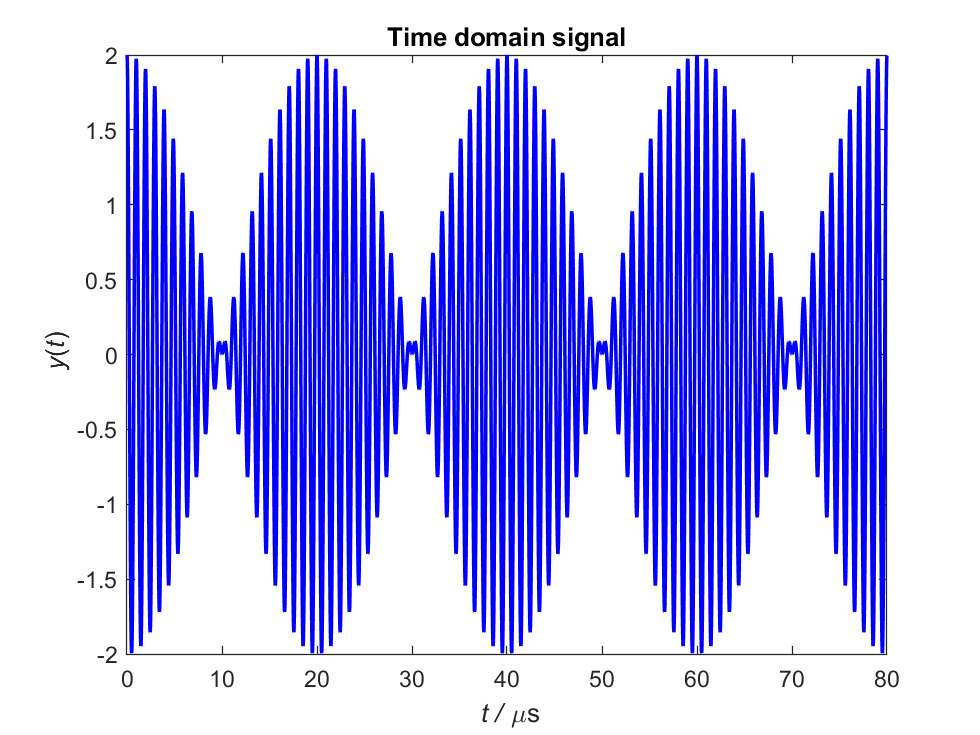


close all; clear; clc

%% FFT
w1 = 1e6;
w2 = 1.05e6;

Fs = 100e6;                                   % 采样频率 Hz
T = 1/Fs;                                     % 采样周期 s

L0 = 8000;                                    % 信号长度
t0 = (0:L0-1)*T;                              % 信号时间序列

x = cos(2*pi*w1*t0) + cos(2*pi*w2*t0);        % 信号函数

L = 8000;                   % 数据长度
t = (0:L-1)*T;              % 数据时间序列
y = zeros(1,L);
y(1:L0) = x;


%% Plot
figure; grid on; 
plot(t*1e6,y,'b-','linewidth',1.5)
title ('Time domain signal')
xlabel('\it t /\rm \mus')
ylabel('\it y\rm(\itt\rm)')

并对其做FFT，结果如下

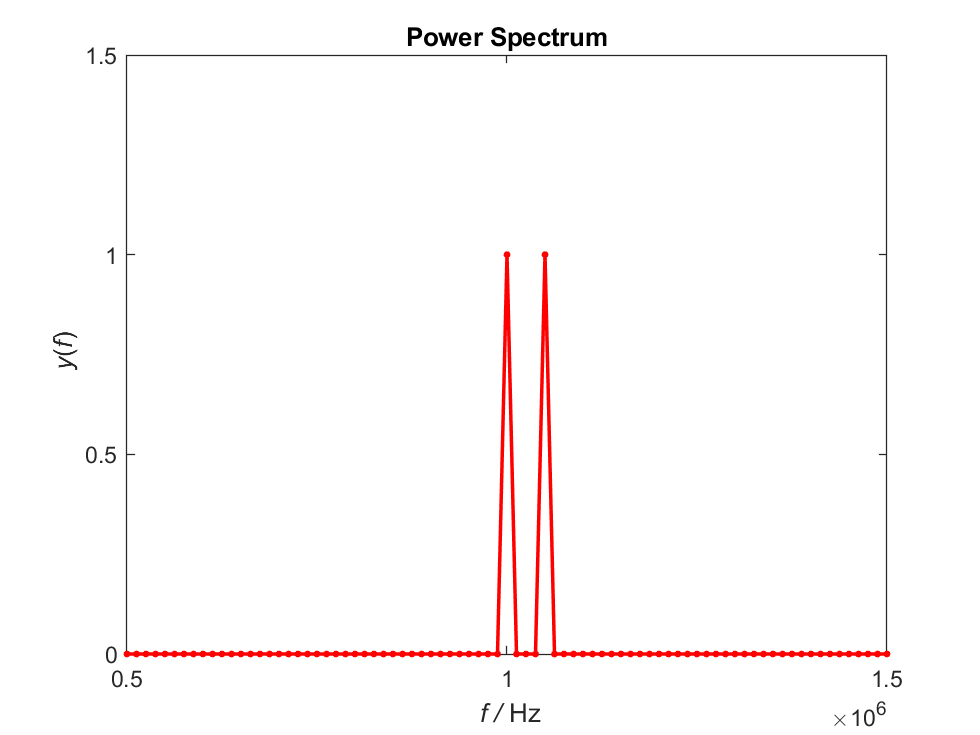

%% FFT
Y = fft(y);                   % 快速傅里叶变换
% 计算双侧频谱 P2。然后基于 P2 和偶数信号长度 L 计算单侧频谱 P1。
P2 = abs(Y/L0);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs/2*linspace(0,1,L/2+1);  % Rfft

figure; grid on; 
plot(f, P1,'r-','Marker','.','markersize',10,'linewidth',1.5)
axis([0.5e6 1.5e6 0 1.5])
title('Power Spectrum')
xlabel('\it f /\rm Hz')
ylabel('\it y\rm(\itf\rm)')

这样就不存在补零带来的误差了。

## FFT convolution without padding


myFilter = fspecial('gaussian', [256 256], 4);
% load source image
myImage = im2double(imread('coins.png')); 
myImage = imresize(myImage, [256 256]);


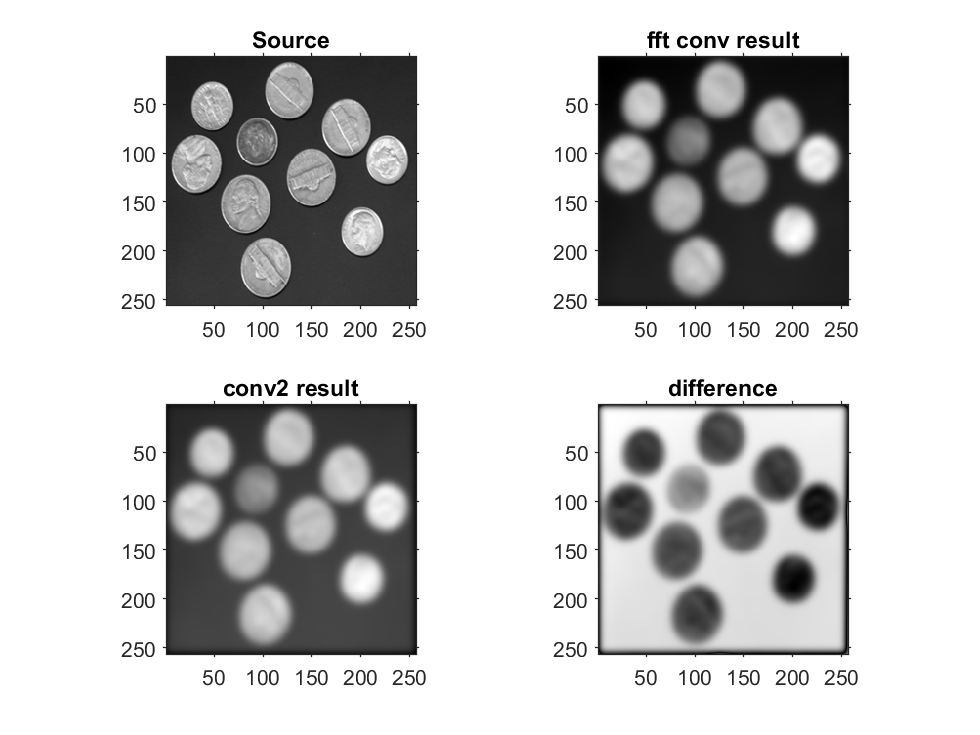

conv = fftshift(ifft2((fft2(myImage) .* fft2(myFilter)))) ;
second_conv = conv2(myImage, myFilter, 'same') ;

figure;
subplot(2,2,1); % 2 rows, 3 columns, grid position 1
imshow(myImage, []);  axis on; title('Source', 'FontSize', 15);
subplot(2,2,2); imshow(conv, []); title('fft conv result', 'FontSize', 15); axis on;
subplot(2,2,3); imshow(second_conv, []); title('conv2 result', 'FontSize', 15); axis on;
subplot(2,2,4); difference = imshowpair(conv, second_conv, 'diff'); title('difference', 'FontSize', 15); axis on; 

### FFT comvolution with padding

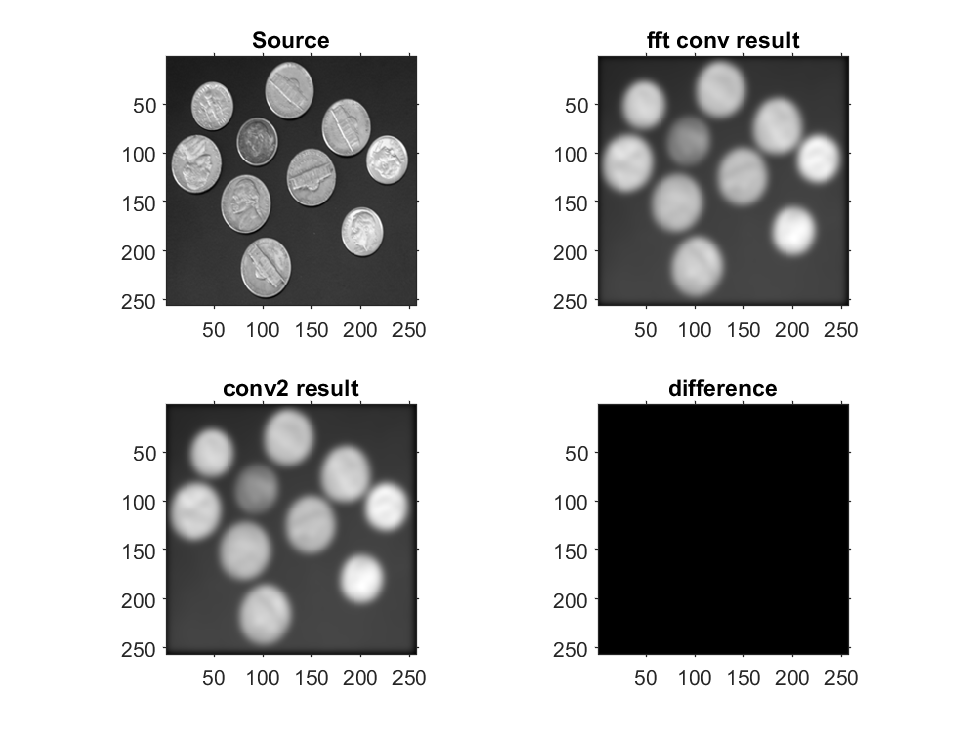

% conv = fftshift(ifft2((fft2(myImage) .* fft2(myFilter)))) ;
% conv = fftconv(myImage, fft2(myFilter));
conv = fftconv_psf(myImage, ifft2(fft2(myFilter)));
% conv = fftconv_otf(myImage, fft2(myFilter));

second_conv = conv2(myImage, myFilter, 'same') ;

figure;
subplot(2,2,1); % 2 rows, 3 columns, grid position 1
imshow(myImage, []);  axis on; title('Source', 'FontSize', 15);
subplot(2,2,2); imshow(conv, []); title('fft conv result', 'FontSize', 15); axis on;
subplot(2,2,3); imshow(second_conv, []); title('conv2 result', 'FontSize', 15); axis on;
subplot(2,2,4); difference = imshowpair(real(conv), second_conv, 'diff');  title('difference', 'FontSize', 15); axis on; 

### 2D image convolution function

%%file ./function/test/fftconv_psf.m

function conv_out = fftconv_psf(x, h)
% 2D linear convolution. out = ifft2(fft2(x).*H)
    [Nx1, Nx2]= size(x);
    [Nh1, Nh2] = size(h);
    
    N1 = Nx1 + Nh1 -1;
    N2 = Nx2 + Nh2 -1;
    
    conv_out = ifft2(fft2(x, N1, N2).*fft2(h, N1, N2));
    
    % padding constants (for output of size == size(A))
    pad1 = ceil((Nh1-1)./2);
    pad2 = ceil((Nh2-1)./2);
    
    % frequency-domain convolution result
    conv_out = conv_out(pad1+1:Nx1+pad1, pad2+1:Nx2+pad2); 
%     conv_out = imresize(conv_out, Nx1, Nx2);    % Doesn't work
end


%%file ./function/test/fftconv_otf.m

function conv_out = fftconv_otf(x, H)
% 2D linear convolution. out = ifft2(fft2(x).*H)
    [Nx1, Nx2]= size(x);
    [NH1, NH2] = size(H);
    
    N1 = Nx1 + NH1 -1;
    N2 = Nx2 + NH2 -1;
    
    x_pad = [x zeros(Nx1, NH2-1); zeros(NH1-1, Nx2 + NH2-1)]; 
    H_pad = [H zeros(NH1, Nx2-1); zeros(Nx1-1, NH2 + Nx2-1)]; 
    
%     conv_out = ifft2(fft2(x, N1, N2).*padarray(H, [floor((N1-NH1)/2), floor((N1-NH1)/2)], 0, 'both'));
    
    conv_out = ifft2(fft2(x_pad).*H_pad);
    
    % padding constants (for output of size == size(A))
    pad1 = ceil((NH1-1)./2);
    pad2 = ceil((NH2-1)./2);
    
    % frequency-domain convolution result
    conv_out = conv_out(pad1+1:Nx1+pad1, pad2+1:Nx2+pad2); 
end
